close all


[vec,val] = eig(E)

vec =    -0.8313    0.5558         0         0
         0         0   -0.9443   -0.3292
    0.5558    0.8313         0         0
         0         0   -0.3292    0.9443


val =     0.0662         0         0         0
         0    0.3807         0         0
         0         0    0.0680         0
         0         0         0    0.0057



[largest_vecidx,r] = find(val == max(max(val)))

largest_vecidx = 2

r = 2

largest_vec = vec(:,largest_vecidx)

largest_vec =     0.5558
         0
    0.8313
         0



largest_val = max(max(val));

evals = diag(val)

evals =     0.0662
    0.3807
    0.0680
    0.0057


smalleig = inf;

for i=1:length(evals)
    if (evals(i) < smalleig)
        smalleig = evals(i)
        evec = vec(:, i)
    end
end

smalleig = 0.0662

evec =    -0.8313
         0
    0.5558
         0


smalleig = 0.0057

evec =          0
   -0.3292
         0
    0.9443



smallest_val = smalleig

smallest_val = 0.0057

smallest_vec = evec

smallest_vec =          0
   -0.3292
         0
    0.9443



angle = atan2(largest_vec(2),largest_vec(1))

angle = 0

if(angle < 0)
    angle = angle + 2*pi;
end


% Get the 95% confidence interval error ellipse
chisquare_val = 2.4477;
theta_grid = linspace(0,2*pi);
phi = angle;
X0=Xp(1);      %Centre of ellipse should be last x,y coords
Y0=Xp(2);      
a=2*4*5.991^0.5

a = 19.5812

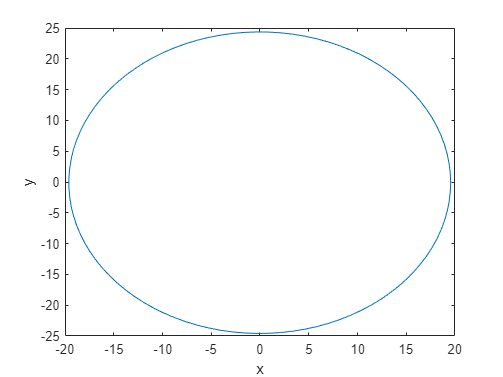

b=2*5*5.991^0.5;

% the ellipse in x and y coordinates 
ellipse_x_r  = a*cos( theta_grid );
ellipse_y_r  = b*sin( theta_grid );

%Define a rotation matrix
R = [ cos(phi) sin(phi); -sin(phi) cos(phi) ];

%let's rotate the ellipse to some angle phi
r_ellipse = [ellipse_x_r;ellipse_y_r]'*R;

% Draw the error ellipse
plot(r_ellipse(:,1) + X0,r_ellipse(:,2) + Y0,'-')
hold on;

% Plot the original data
% plot(data(:,1), data(:,2), '.');
% mindata = min(min(data));
% maxdata = max(max(data));
% xlim([mindata-3, maxdata+3]);
% ylim([mindata-3, maxdata+3]);
% hold on;

% Plot the eigenvectors
% quiver(X0, Y0, largest_vec(1)*sqrt(largest_val), largest_vec(2)*sqrt(largest_val), '-m', 'LineWidth',2);
% quiver(X0, Y0, smallest_vec(1)*sqrt(smallest_val), smallest_vec(2)*sqrt(smallest_val), '-g', 'LineWidth',2);
% hold on;

% Set the axis labels
hXLabel = xlabel('x');
hYLabel = ylabel('y');